%syms M m1 m2 l1 l2 g

M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

## A_f and B_f matrices

A_f =[0 1 0 0 0 0;0 0 (-m1*g)/M 0 (-m2*g)/M 0;0 0 0 1 0 0;0 0 -(g/l1)*((m1+M)/M) 0 (-m2*g)/M*l1 0;0 0 0 0 0 1;0 0 (-m1*g)/M*l2 0 -(g/l2)*((m2+M)/M) 0]

A_f =          0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5396         0  -19.6200         0
         0         0         0         0         0    1.0000
         0         0   -9.8100         0   -1.0791         0


B_f =[0;1/M;0;1/(M*l1);0;1/(M*l2)]

B_f = 	1.0e+-3 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


eigs(A_f)

ans =   -0.0000 + 3.8322i
  -0.0000 - 3.8322i
  -3.6148 + 0.0000i
   3.6148 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


C = diag([1 1 1 1 1 1])

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D = [0;0;0;0;0;0]

D =      0
     0
     0
     0
     0
     0



plant = ss(A_f,B_f,C,D);
Plant_poles = pole(plant);

## Controllability Matrix and rank condition

Co = ctrb(plant)

Co =          0    0.0010         0   -0.0001         0    0.0025
    0.0010         0   -0.0001         0    0.0025         0
         0    0.0001         0   -0.0020         0    0.0128
    0.0001         0   -0.0020         0    0.0128         0
         0    0.0001         0   -0.0006         0    0.0202
    0.0001         0   -0.0006         0    0.0202         0


Ob = obsv(plant)

Ob = 	1.0e+03 *

    0.0010         0         0         0         0         0
         0    0.0010         0         0         0         0
         0         0    0.0010         0         0         0
         0         0         0    0.0010         0         0
         0         0         0         0    0.0010         0
         0         0         0         0         0    0.0010
         0    0.0010         0         0         0         0
         0         0   -0.0010         0   -0.0010         0
         0         0         0    0.0010         0         0
         0         0   -0.0005         0   -0.0196         0


rank_Co = rank(Co)

rank_Co = 6

eig_Co = eigs(Co)

eig_Co =     0.0198
   -0.0198
   -0.0016
    0.0016
    0.0010
   -0.0010


rank_Ob = rank(Ob)

rank_Ob = 6

%eig_Ob = eigs(Ob)

## Initial conditions

I = [0;1;1;0;1;0]

I =      0
     1
     1
     0
     1
     0


## Plant

%Q = [1200000000 1 0 0 0 0;1 3 0 0 0 0;0 0 1100000000 0 0 0 ; 0 0 0 1 0 0;0 0 0 0 1400000000 0;0 0 0 0 0 2]
Q = [1200000000000 10 0 0 0 0;10 2 0 0 0 0;0 0 11000000000000 0 0 0 ; 0 0 0 0.1 0 0;0 0 0 0 14000000000000 0;0 0 0 0 0 1]

Q = 	1.0e+13 *

    0.1200    0.0000         0         0         0         0
    0.0000    0.0000         0         0         0         0
         0         0    1.1000         0         0         0
         0         0         0    0.0000         0         0
         0         0         0         0    1.4000         0
         0         0         0         0         0    0.0000


R = 10

R = 10

eig_Q = eigs(Q)

eig_Q = 	1.0e+13 *

    1.4000
    1.1000
    0.1200
    0.0000
    0.0000
    0.0000


N = [1;2;3;1;5;2]

N =      1
     2
     3
     1
     5
     2



PSD = [Q N;N' R]

PSD = 	1.0e+13 *

    0.1200    0.0000         0         0         0         0    0.0000
    0.0000    0.0000         0         0         0         0    0.0000
         0         0    1.1000         0         0         0    0.0000
         0         0         0    0.0000         0         0    0.0000
         0         0         0         0    1.4000         0    0.0000
         0         0         0         0         0    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


%eig_PSD = eigs(PSD)

[K2,S2,e2] = lqr(A_f+eye(size(A_f)),B_f,Q,R,N)

K2 = 	1.0e+07 *

   -0.0763   -0.0589   -2.8052   -0.6839    3.0355    0.9735


S2 = 	1.0e+15 *

    0.0023    0.0011    0.0360    0.0081   -0.0442   -0.0150
    0.0011    0.0006    0.0226    0.0048   -0.0245   -0.0089
    0.0360    0.0226    0.8753    0.1910   -0.9032   -0.3241
    0.0081    0.0048    0.1910    0.0429   -0.2012   -0.0703
   -0.0442   -0.0245   -0.9032   -0.2012    1.0050    0.3488
   -0.0150   -0.0089   -0.3241   -0.0703    0.3488    0.1250


e2 =  -13.5859 +13.6057i
 -13.5859 -13.6057i
  -4.5397 + 0.0000i
  -1.1921 + 3.6421i
  -1.1921 - 3.6421i
  -2.6311 + 0.0000i


A_cl = A_f-(B_f*K2)

A_cl = 	1.0e+04 *

         0    0.0001         0         0         0         0
    0.0763    0.0589    2.8051    0.6839   -3.0356   -0.9735
         0         0         0    0.0001         0         0
    0.0038    0.0029    0.1402    0.0342   -0.1537   -0.0487
         0         0         0         0         0    0.0001
    0.0076    0.0059    0.2795    0.0684   -0.3037   -0.0973



Plant_LQR = ss(A_cl,B_f,C,D)


Plant_LQR =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2       762.8       588.8   2.805e+04        6839  -3.036e+04       -9735
   x3           0           0           0           1           0           0
   x4       38.14       29.44        1402         342       -1537      -486.7
   x5           0           0           0           0           0           1
   x6       76.28       58.88        2795       683.9       -3037      -973.5
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
Continuous-time state-spa

%step(Plant_LQR)

## Luenberger Observer Design 

pole(Plant_LQR)

ans =  -14.5859 +13.6057i
 -14.5859 -13.6057i
  -2.1921 + 3.6421i
  -2.1921 - 3.6421i
  -5.5397 + 0.0000i
  -3.6311 + 0.0000i


%A_hat = 
Poles_L_Obs = [-28;-30;-10;-6;-2;-4]

Poles_L_Obs =    -28
   -30
   -10
    -6
    -2
    -4




L = place(A_f',C',Poles_L_Obs)'

L =    28.0000    1.0000         0         0         0         0
         0   30.0000   -0.9810         0   -0.9810         0
         0         0   10.0000    1.0000         0         0
         0         0   -0.5396    6.0000  -19.6200         0
         0         0         0         0    2.0000    1.0000
         0         0   -9.8100         0   -1.0791    4.0000



Luen_SYS = ss(A_f-L*C,B_f,C,D)


Luen_SYS =
 
  A = 
        x1   x2   x3   x4   x5   x6
   x1  -28    0    0    0    0    0
   x2    0  -30    0    0    0    0
   x3    0    0  -10    0    0    0
   x4    0    0    0   -6    0    0
   x5    0    0    0    0   -2    0
   x6    0    0    0    0    0   -4
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
   y6   0
 
Continuous-time state-space model.



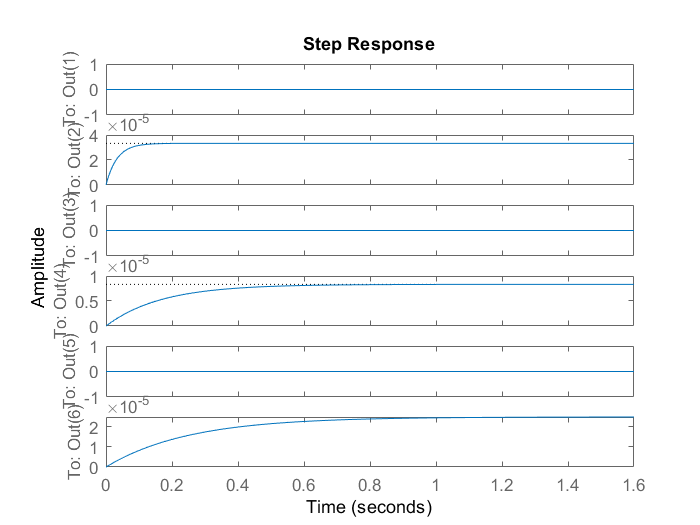

step(Luen_SYS)

## Luenberger Observer Design 


[A_c,B_c,C_c,D_c] = reg(A_f,B_f,C,D,K2,L)

A_c = 	1.0e+04 *

   -0.0028         0         0         0         0         0
    0.0763    0.0559    2.8052    0.6839   -3.0355   -0.9735
         0         0   -0.0010         0         0         0
    0.0038    0.0029    0.1403    0.0336   -0.1518   -0.0487
         0         0         0         0   -0.0002         0
    0.0076    0.0059    0.2805    0.0684   -0.3035   -0.0977


B_c =    28.0000    1.0000         0         0         0         0
         0   30.0000   -0.9810         0   -0.9810         0
         0         0   10.0000    1.0000         0         0
         0         0   -0.5396    6.0000  -19.6200         0
         0         0         0         0    2.0000    1.0000
         0         0   -9.8100         0   -1.0791    4.0000


C_c = 	1.0e+07 *

   -0.0763   -0.0589   -2.8052   -0.6839    3.0355    0.9735


D_c =      0     0     0     0     0     0



%step(ss(A_c,B_c,C_c,D_c))

C_Lo = ctrb(A_f',C')

C_Lo = 	1.0e+03 *

    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0         0         0         0    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0010         0         0         0         0   -0.0010         0   -0.0005         0   -0.0098   -0.0010         0   -0.0005         0   -0.0098         0         0    0.0102         0    0.1928         0    0.0159    0.0102         

rank(C_Lo)

ans = 6

Ob_Lo = obsv(A_f,C)

Ob_Lo = 	1.0e+03 *

    0.0010         0         0         0         0         0
         0    0.0010         0         0         0         0
         0         0    0.0010         0         0         0
         0         0         0    0.0010         0         0
         0         0         0         0    0.0010         0
         0         0         0         0         0    0.0010
         0    0.0010         0         0         0         0
         0         0   -0.0010         0   -0.0010         0
         0         0         0    0.0010         0         0
         0         0   -0.0005         0   -0.0196         0


rank(Ob_Lo)

ans = 6




%step(ss(A_c,B_c,C_c,D_c))

At = [ A_f-B_f*K2             B_f*K2
       zeros(size(A_f))    A_f-L*C ];

Bt = [    B_f
       zeros(size(B_f)) ];

Ct = [ C    zeros(size(C)) ];

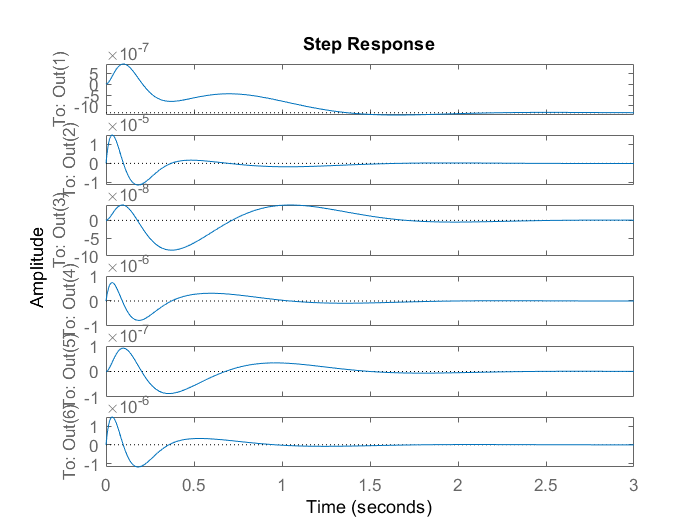

step(ss(At,Bt,Ct,0))